# Modeling and Autotuning of the iCub 2 head

## Run the simplified project

We first load the project dedicated to modelling and autotuning.

if isempty(matlab.project.rootProject)
    open('model-simplified/neck-study-simplified.prj')
elseif (currentProject().Name == "neck-study-full")
    close(currentProject());
    open('model-simplified/neck-study-simplified.prj')
end

### Create uncertain transfer functions

Our objective is to control roll and pitch of the head through discrete PID controllers.

 To do so, we use a Simscape Multibody model made by lumped up components. This model is used to create two decoupled systems, linearized at different operating points.

create_uncertain_models

ans = 'Finding operating point for pitch=-40.0'

ans = 'Finding operating point for pitch=0.0'

ans = 'Finding operating point for pitch=22.0'

ans = 'Finding operating point for roll=-20.0'

ans = 'Finding operating point for roll=0.0'

ans = 'Finding operating point for roll=20.0'

Here is the nominal transfer function between  the pitch PID controller and the pitch angle:

zpk(tfu_pitch.NominalValue)

ans =
 
               3.0588e06 (s+10)
  -------------------------------------------
  (s+1.587e04) (s+60.44) (s+10.08) (s-0.8391)
 
Continuous-time zero/pole/gain model.



And here is the nominal transfer function between the roll PID controller and the roll angle:

zpk(tfu_roll.NominalValue)

ans =
 
              3.6843e06 (s+10)
  ----------------------------------------
  (s+1.597e04) (s+72.3) (s+10.06) (s-0.73)
 
Continuous-time zero/pole/gain model.



Since the head is an inverted pendulum with two degrees of freedom, we find unstable poles that constitute the dominant modes of the two systems. The unstable poles are modelled with uncertainties depending on the chosen operating points.

### Launch autotuning algorithm

After computing the models, we can launch the automated robust tuning algorithm. The method works by creating two feedback systems made by the models and two decoupled continuous PID controllers. 

The controllers are then tuned iteratively with built-in robust algorithms. Finally, the controllers are discretized, for implementation on uC.

Nominal tuning:
Design 1: Soft = 1.44, Hard = 1.0275
Design 2: Soft = 1.44, Hard = 1.0275
Design 3: Soft = 1.44, Hard = 1.0275
Design 4: Soft = 1.44, Hard = 1.0275
Design 5: Soft = 1.44, Hard = 1.0275
Design 6: Soft = 1.44, Hard = 1.0275

Robust tuning of Design 3:
Soft: [1.44,Inf], Hard: [1.03,2.52], Iterations = 52
Soft: [1.46,Inf], Hard: [1.34,1.65], Iterations = 35
Soft: [1.48,Inf], Hard: [1.5,1.5], Iterations = 27
Final: Soft = 1.48, Hard = 1.5006, Iterations = 114

Robust tuning of Design 6:
Soft: [1.44,Inf], Hard: [1.03,2.52], Iterations = 40
Soft: [1.46,Inf], Hard: [1.34,1.65], Iterations = 33
Soft: [1.48,Inf], Hard: [1.5,1.5], Iterations = 27
Final: Soft = 1.48, Hard = 1.5006, Iterations = 100

Robust tuning of Design 1:
Soft: [1.44,Inf], Hard: [1.03,2.52], Iterations = 79
Soft: [1.46,Inf], Hard: [1.34,1.65], Iterations = 32
Soft: [1.48,Inf], Hard: [1.5,1.5], Iterations = 27
Final: Soft = 1.48, Hard = 1.5006, Iterations = 138

Robust tuning of Design 2:
Soft: [1.44,Inf], Hard:

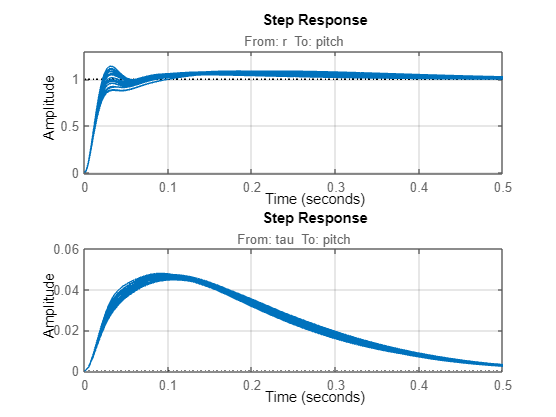

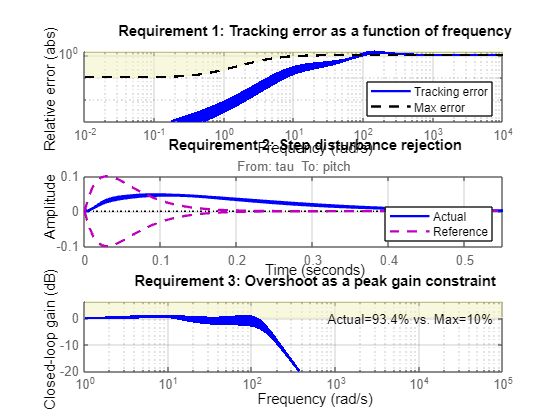

Nominal tuning:
Design 1: Soft = 1.43, Hard = 0.99957
Design 2: Soft = 1.43, Hard = 0.99993
Design 3: Soft = 1.43, Hard = 0.99983
Design 4: Soft = 1.43, Hard = 0.99969
Design 5: Soft = 1.43, Hard = 0.99971
Design 6: Soft = 1.43, Hard = 0.99974

Robust tuning of Design 2:
Soft: [1.43,Inf], Hard: [1,2.62], Iterations = 197
Soft: [1.46,Inf], Hard: [1.3,1.61], Iterations = 33
Soft: [1.48,Inf], Hard: [1.46,1.46], Iterations = 32
Final: Soft = 1.48, Hard = 1.4638, Iterations = 262

Robust tuning of Design 3:
Soft: [1.43,Inf], Hard: [1,2.62], Iterations = 176
Soft: [1.46,Inf], Hard: [1.3,1.61], Iterations = 33
Soft: [1.48,Inf], Hard: [1.46,1.46], Iterations = 32
Final: Soft = 1.48, Hard = 1.4638, Iterations = 241

Robust tuning of Design 6:
Soft: [1.43,Inf], Hard: [1,2.62], Iterations = 175
Soft: [1.46,Inf], Hard: [1.3,1.61], Iterations = 33
Soft: [1.48,Inf], Hard: [1.46,1.46], Iterations = 32
Final: Soft = 1.48, Hard = 1.4638, Iterations = 240

Robust tuning of Design 5:
Soft: [1.43,Inf], Ha

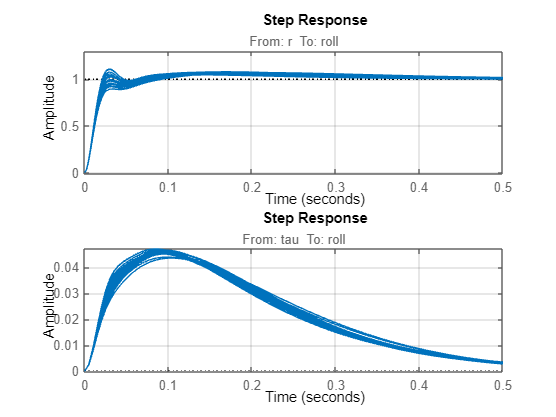

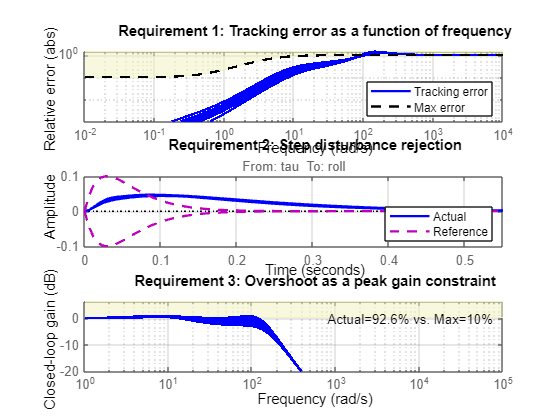

launch_autotune

## Run the full project

We load the project containing the full fledged model of the head, to validate the controller.

if isempty(matlab.project.rootProject)
    open('model-full/neck-study-full.prj')
elseif (currentProject().Name == "neck-study-simplified")
    close(currentProject());
    open('model-full/neck-study-full.prj')
end

#### Check if controllers exist

Load the .mat file containing the pitch and roll controllers if they are not instantiated.

if(isempty('Cz_pitch') || isempty('Cz_roll'))
    if(~exist('data/pitch_roll_controllers.mat','file'))
        error('Pitch and roll controllers not found.')
    else
        load('data/pitch_roll_controllers.mat');
    end
end

### Run the simulation

To validate the autotuned PID controllers we run a simulation containing the full-fledged Simscape Multibody model. The model is the result of the 

out = sim('models/neck_head_control.slx');